# **Hopf Investigation**

clc; clear all; close all;


Symbolically defining the first chart, we can find the rotation axis they used --> which gives us the minimal rotation from $\vec{e}_3 \rightarrow \mathbf{t} = [a, b, c]$ where t is the thrust direction. 

syms a b c real
assumeAlso(a^2 + b^2 + c^2 == 1)
assumeAlso(c > -1) % <-- avoids singularity, implies c+1>0
t = [a; b; c];
q = (1/(2*sqrt(1+c))) * [1+c; -b; a; 0];
v = q(2:end);
n = simplify(v / norm(v), 'Steps', 50)

$$n = \left(\begin{array}{c} -\frac{b}{\sqrt{1-c^{2}}}\\ \frac{a}{\sqrt{1-c^{2}}}\\ 0 \end{array}\right)$$

We can visualize this:

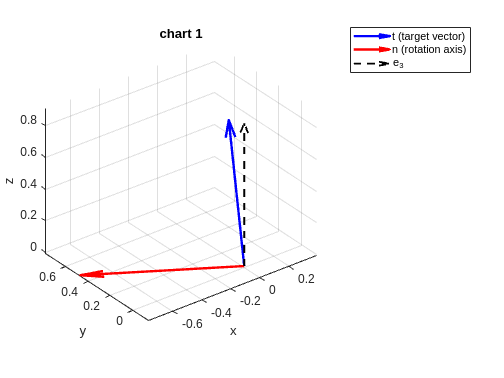

% random unit vector on S^2
t = rand(3,1);
t = t / norm(t);
a = t(1);
b = t(2);
c = t(3);
% quaternion vector part
v = [-b; a; 0];
% normalize to get rotation axis
n = v / norm(v);
figure; hold on; grid on; axis equal;
xlabel('x'); ylabel('y'); zlabel('z');
view(3);
title('chart 1')
% origin
O = [0;0;0];
% plot t (blue)
quiver3(O(1),O(2),O(3), t(1),t(2),t(3), ...
    'LineWidth',2,'Color','b','MaxHeadSize',0.5);
% plot n (red)
quiver3(O(1),O(2),O(3), n(1),n(2),n(3), ...
    'LineWidth',2,'Color','r','MaxHeadSize',0.5);
% reference e3
e3 = [0;0;1];
quiver3(0,0,0,e3(1),e3(2),e3(3), ...
    'LineWidth',1.5,'Color','k','LineStyle','--');
legend('t (target vector)','n (rotation axis)','e_3');

Now, the second mapping:

syms a b c real
assumeAlso(a^2 + b^2 + c^2 == 1)
assumeAlso(c < 1) % <-- avoids singularity, implies c-1>0
t = [a; b; c];
q = (1/(2*sqrt(1-c))) * [-b; 1-c; 0; a];
v = q(2:end);
n = simplify(v / norm(v), 'Steps', 50)

$$n = \left(\begin{array}{c} -\frac{c-1}{\sqrt{-b^{2}-2\,c+2}}\\ 0\\ \frac{a}{\sqrt{-b^{2}-2\,c+2}} \end{array}\right)$$

How did they get to this? We know that we need it to be singular at c = -1. 

We can visualize this:

% random unit vector on S^2
t = -rand(3,1)

t =    -0.5828
   -0.8154
   -0.8790


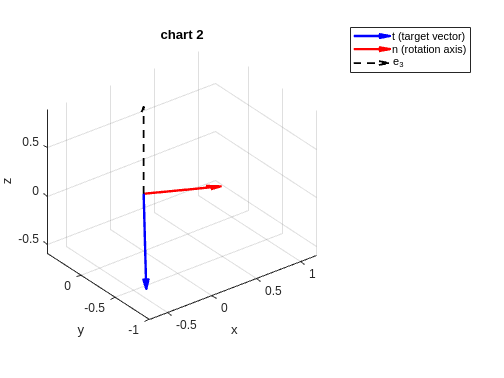

t = t / norm(t);
a = t(1);
b = t(2);
c = t(3);
% quaternion vector part
v = [1-c; 0; a];
% normalize to get rotation axis
n = v / norm(v);
figure; hold on; grid on; axis equal;
xlabel('x'); ylabel('y'); zlabel('z');
view(3);
title('chart 2')
% origin
O = [0;0;0];
% plot t (blue)
quiver3(O(1),O(2),O(3), t(1),t(2),t(3), ...
    'LineWidth',2,'Color','b','MaxHeadSize',0.5);
% plot n (red)
quiver3(O(1),O(2),O(3), n(1),n(2),n(3), ...
    'LineWidth',2,'Color','r','MaxHeadSize',0.5);
% reference e3
e3 = [0;0;1];
quiver3(0,0,0,e3(1),e3(2),e3(3), ...
    'LineWidth',1.5,'Color','k','LineStyle','--');
legend('t (target vector)','n (rotation axis)','e_3');

Lets investigate the transition (c = 0)

% unit vector on S^2 with zero z component
t = -randn(3,1)

t =    -1.1706
   -0.4759
   -1.4122


t(3) = 0

t =    -1.1706
   -0.4759
         0


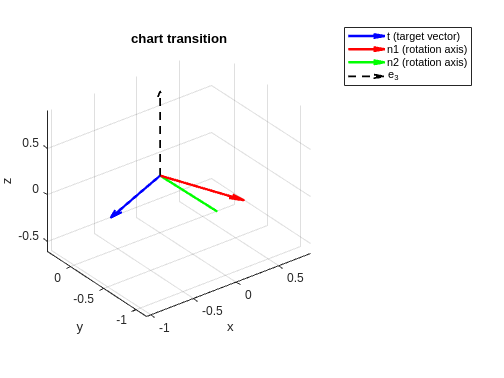

t = t / norm(t);
a = t(1);
b = t(2);
c = t(3);

% quaternion vector part
v1 = [-b; a; 0];
% normalize to get rotation axis
n1 = v1 / norm(v1);

% quaternion vector part
v2 = [1-c; 0; a];
% normalize to get rotation axis
n2 = v2 / norm(v2);

figure; hold on; grid on; axis equal;
xlabel('x'); ylabel('y'); zlabel('z');
view(3);
title('chart transition')
% origin
O = [0;0;0];
% plot t (blue)
quiver3(O(1),O(2),O(3), t(1),t(2),t(3), ...
    'LineWidth',2,'Color','b','MaxHeadSize',0.5);
% plot n1 (red)
quiver3(O(1),O(2),O(3), n1(1),n1(2),n1(3), ...
    'LineWidth',2,'Color','r','MaxHeadSize',0.5);
% plot n2 (green)
quiver3(O(1),O(2),O(3), n2(1),n2(2),n2(3), ...
    'LineWidth',2,'Color','g','MaxHeadSize',0.5);
% reference e3
e3 = [0;0;1];
quiver3(0,0,0,e3(1),e3(2),e3(3), ...
    'LineWidth',1.5,'Color','k','LineStyle','--');


legend('t (target vector)','n1 (rotation axis)','n2 (rotation axis)','e_3');

symbolically:

% random unit vector on S^2, avoid poles
t = randn(3,1); 
t(3) = 0; t = t/norm(t);
a=t(1); b=t(2); c=t(3);


if abs(1+c) < 1e-3 || abs(1-c) < 1e-3
    error("Too close to a pole; rerun.");
end

% chart 1 section
qabc = (1/sqrt(2*(1+c))) * [1+c; -b; a; 0];

% chart 2 section
q_bar_abc = (1/sqrt(2*(1-c))) * [-b; 1-c; 0; a];

% theoretical desired yaw
psi = 0.3;

% psi offset
psi_bar = psi + 2* atan2(-a, -b); 

% functions
q_z = @(psi) [cos(psi/2); 0; 0; sin(psi/2)];
qmul = @(p,q) [ ...
    p(1)*q(1) - p(2)*q(2) - p(3)*q(3) - p(4)*q(4);
    p(1)*q(2) + p(2)*q(1) + p(3)*q(4) - p(4)*q(3);
    p(1)*q(3) - p(2)*q(4) + p(3)*q(1) + p(4)*q(2);
    p(1)*q(4) + p(2)*q(3) - p(3)*q(2) + p(4)*q(1) ];

% compare transition function
q_psi = q_z(psi)

q_psi =     0.9888
         0
         0
    0.1494


q_psi_bar = q_z(psi_bar)

q_psi_bar =     0.9579
         0
         0
   -0.2871


q = qmul(qabc, q_psi)

q =     0.6992
    0.6773
    0.2030
    0.1057


q_bar = qmul(q_bar_abc, q_psi_bar)

q_bar =     0.6992
    0.6773
    0.2030
    0.1057


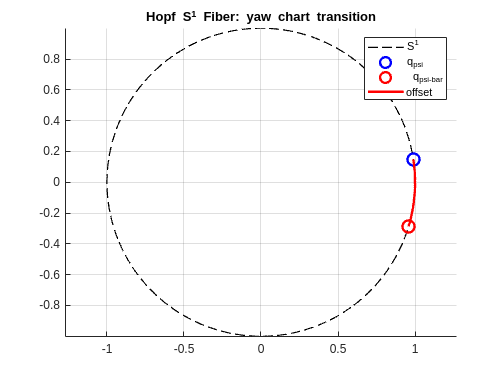

% plot S1
qpsi     = [q_psi(1); q_psi(4)];
qpsibar  = [q_psi_bar(1); q_psi_bar(4)];
theta = linspace(0,2*pi,400);
figure; hold on; axis equal; grid on;
plot(cos(theta), sin(theta), 'k--', 'LineWidth', 1);

% plot points
plot(qpsi(1),    qpsi(2),    'bo', 'MarkerSize',10, 'LineWidth',2);
plot(qpsibar(1), qpsibar(2), 'ro', 'MarkerSize',10, 'LineWidth',2);

% draw arc showing offset
arc_theta = linspace(psi/2, psi_bar/2, 100);
plot(cos(arc_theta), sin(arc_theta), 'r', 'LineWidth',2);

legend('S^1','q_{psi}',' q_{psi-bar}','offset');
title('Hopf S^1 Fiber: yaw chart transition');